# Problem 1: Design case study- Helicopter Loops

clc ; clear;
syms kappa omega x C1 C2 C3 C4 Mhub K E I theta R d t real
syms V positive real

## b) Method to calculate Tip-Deflection

Using Euler Bernaulli Beam equation.

q = kappa*(V+x*omega)^2;

% Integration of Load-Intensity gives Shear-Force
Q = int(q,x) + C1;
Q_bound = subs(Q,x,d/2) == 0;
C1_val = solve(Q_bound,C1);
Q_val = subs(Q,C1,C1_val);

% Integration of Shear-Frce gives Bending-Moment
M = int(Q_val,x) + C2;
M_bound = subs(M,x,d/2) == 0;
C2_val = solve(M_bound,C2);
M_val = subs(M,C2,C2_val);

% Integration of Bending-Moment gives Slope(theta)
A = int(M_val,x) + C3;
A_bound = subs(A,x,0) == Mhub/K;
C3_val = solve(A_bound,C3);
A_val = subs(A,C3,C3_val);

% Integration of Slope(theta) gives Deflection 
w = int(A_val,x) + C4;
w_bound = subs(w,x,0) == 0;
C4_val = solve(w_bound,C4);
w_val = subs(w,C4,C4_val)

$$w\_val = \frac{V^{2}\,\kappa \,x^{4}}{24}+\frac{\kappa \,\omega^{2}\,x^{6}}{360}+\frac{\mathrm{Mhub}\,x}{K}+\frac{d^{2}\,\kappa \,x^{2}\,\left(24\,V^{2}+16\,V\,d\,\omega +3\,d^{2}\,\omega^{2}\right)}{384}+\frac{V\,\kappa \,\omega \,x^{5}}{60}-\frac{d\,\kappa \,x^{3}\,\left(12\,V^{2}+6\,V\,d\,\omega +d^{2}\,\omega^{2}\right)}{144}$$


% Deflection at Tip
w_tip = simplify(subs(w_val,x,d/2))/(E*I)

$$w\_tip = \frac{d\,\left(90\,K\,\kappa \,V^{2}\,d^{3}+66\,K\,\kappa \,V\,d^{4}\,\omega +13\,K\,\kappa \,d^{5}\,\omega^{2}+5760\,\mathrm{Mhub}\right)}{11520\,\text{E}\,\text{I}\,K}$$

## c) Sketch that explains how bending stress and shear stress varies at the root.

NOTE : Taking corresponding values to the different parameters according to the information available on the internet.

Omega (41.81 rad/s) is mostly kept constant in flight and just the pitch of the rotor blades are changed to vary the CT(coefficient of thrust).

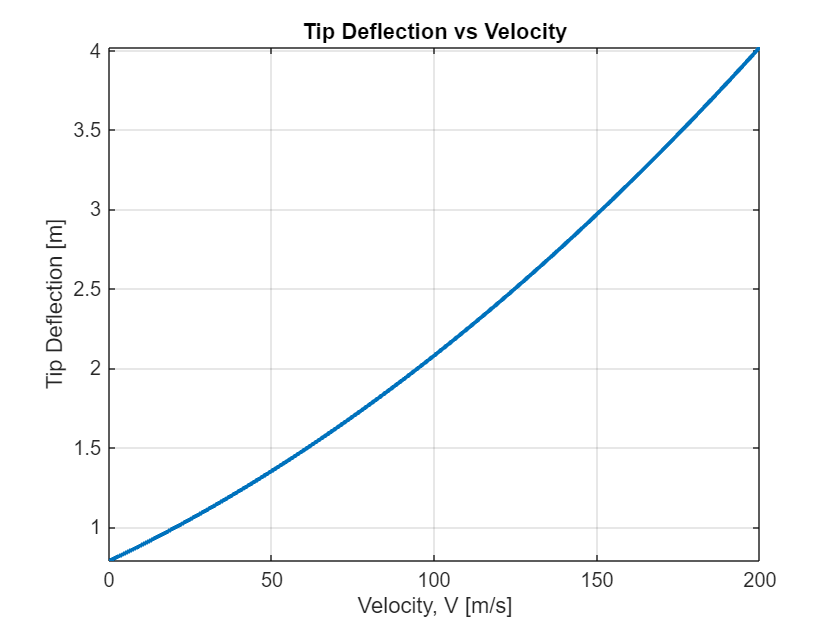

% Values corresponding to MBB Bo 105 Helicopter
K_val = 10^6;                 % stiffness of the hub [N-m/rad]
d_val = 9.82;                 % Rotor diameter [m]
c_val = 0.27;                 % Blade chord [m]
t_val = 0.1;                  % Blade thickness [m]
omega_val = 41.81;            % Rotor speed [rad/s]
kappa_val = 1;                % Lift distribution parameter [N/m^3]
E_val = 100 * 10^9;           % Young's modulus of the blade material [Pa = N/m^2]
Ar = c_val * t_val;           % Cross-sectional area of the blade [m^2]
I_val = c_val * t_val^3 / 12; % Mmoment of inertia of the blade cross-section [m^4]

%Moment generated by Stiffness
Mhub_val = subs(int(q*x,x,0,d/2),[d,K,omega,kappa],[d_val,K_val,omega_val,kappa_val]);

%Tip deflection variation with V
tip_deflection = simplify(subs(w_tip,[kappa,K,d,omega,E,I,Mhub],[kappa_val,K_val,d_val,omega_val,E_val,I_val,Mhub_val]));
figure;
fplot(tip_deflection,[0,200], 'LineWidth', 2);
title('Tip Deflection vs Velocity');
xlabel('Velocity, V [m/s]');
ylabel('Tip Deflection [m]');
grid on;

I am assuming the tip deflection should not surpass 1m, the corresponding Velocity would be the permissible maneuver speed.

eq1 = tip_deflection == 1;
double(solve(eq1,V))

ans = 20.5837

The permissible maneuver speed V = 20.5837 m/s.

%Load factor
V_val = 20.5837

V_val = 20.5837

R_val = 30

R_val = 30

g = 9.8

g = 9.8000

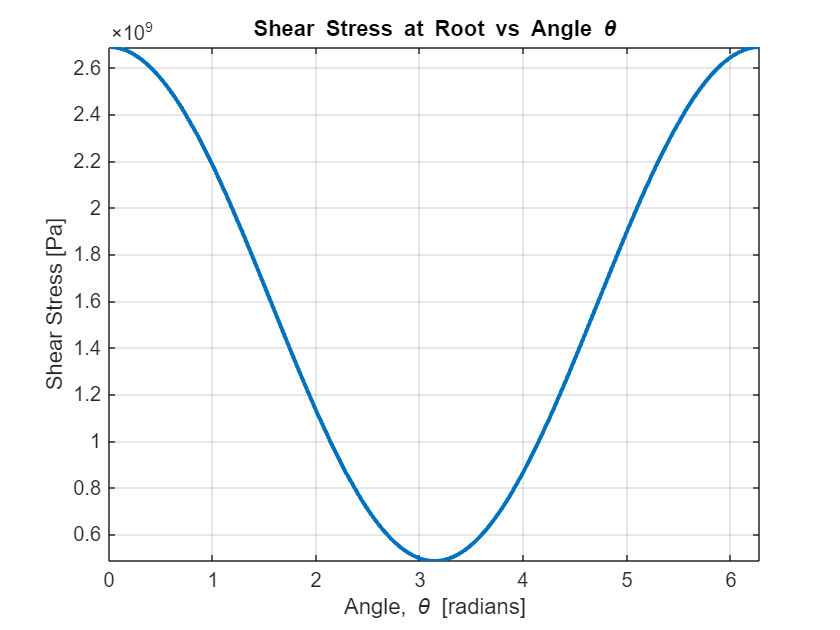

n_theta = (V_val^2 / (g * R_val)) +cos(theta);

%shear stress calculation
sforce = int(q,x,0,d/2);
Shear_stress = simplify(sforce*Ar/(I*t)*n_theta);
SS_root = simplify(subs(Shear_stress, [kappa, K, d, omega, E, I, Mhub, x, t, V], ...
    [kappa_val, K_val, d_val, omega_val, E_val, I_val, Mhub_val, 0, t_val,20.5837]));

figure;
fplot(SS_root, [0, 2*pi], 'LineWidth', 2)
title('Shear Stress at Root vs Angle \theta');
xlabel('Angle, \theta [radians]');
ylabel('Shear Stress [Pa]');
grid on;

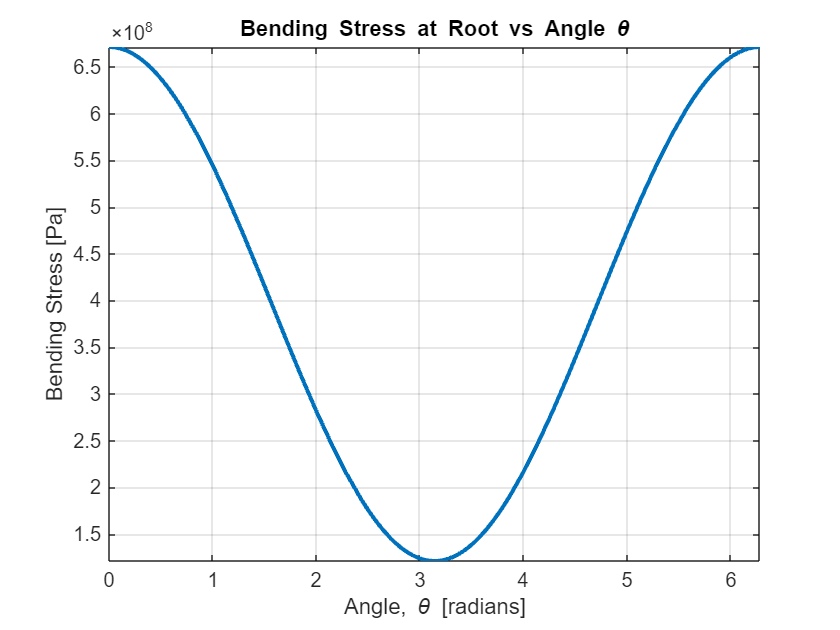


% Bending stress calculation
M_eq = int(int(q, x), 0, d/2);
Bending_stress = simplify(M_eq * (t / 2) / I * n_theta);

BS_root = simplify(subs(Bending_stress, [kappa, K, d, omega, E, I, Mhub, x, t, V], ...
    [kappa_val, K_val, d_val, omega_val, E_val, I_val, Mhub_val, 0, t_val, V_val]));
figure;
fplot(BS_root, [0, 2*pi], 'LineWidth', 2);
title('Bending Stress at Root vs Angle \theta');
xlabel('Angle, \theta [radians]');
ylabel('Bending Stress [Pa]');
grid on;